%   Paramètres de similuation
Te = 1e-7;
Fs = 1/Te;
Tf = 0.3;
len = Tf/Te

len = 3000000

t = (0:len-1)*Te; 

f = 60;
L = 0.002;
C = 640e-6;
R1 = 1.5e3;
R2 = 200;
up = 1

up = 1

Req = ((R1*R2)/(R1+R2))*up + R1*(1-up)

Req = 176.4706

Im = 8.7; 
Vc=500;
Vr=230;
Vr_max = 230*sqrt(2);
I_M = sqrt(2) * (Vc)^2/(Vr*Req)

I_M = 8.7107


theta = 2*pi*f*t; % linspace(0,pi,2e6);
Fd = 12e3;
w =2*f*pi

w = 376.9911

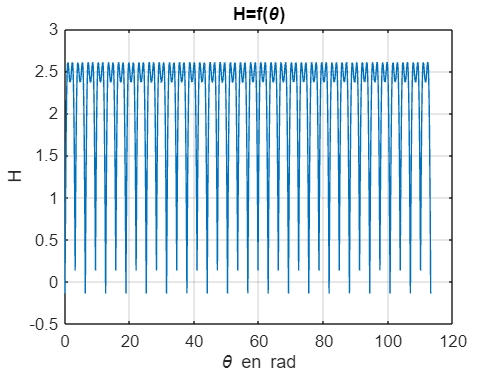

m = I_M*w*cos(theta);
Vrd= abs(Vr_max*sin(theta));
H_ = ((Vrd-m*L).*(Vc -Vrd+ m*L))./(2*Fd*L*Vc);
plot(theta, H_);grid on;
title("H=f(\theta)");
ylabel("H")
xlabel("\theta en rad");

h = min(H_)

h = -0.1386

hm = max(H_)

hm = 2.6042



% delta = 0 et H != 0
%H = Im/10;
H =max(H_);
epson =  H;
epsoff= -H;
Son = 1;
Soff = -1;

sim("Modeele_cvs_pfc_avec_hysteresis.slx")

ans =   Simulink.SimulationOutput:

                     Il: [1x1 timeseries] 
                     Ir: [1x1 timeseries] 
                   Iref: [1x1 timeseries] 
                     Vc: [1x1 timeseries] 
                    Vrd: [1x1 timeseries] 
                   tout: [3000001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


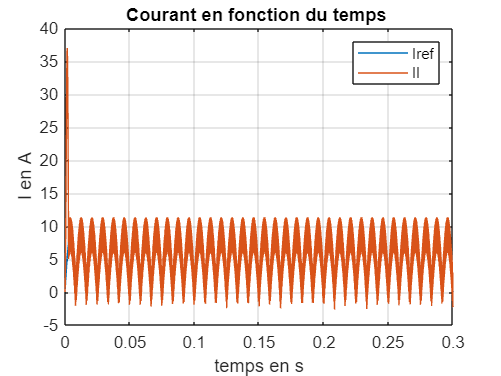

%Affichage
% plot(ans.Ir.Time, ans.Ir.Data);
% hold on;
plot(ans.Iref.Time, ans.Iref.Data);
hold on;
plot(ans.Il.Time, ans.Il.Data);

title("Courant en fonction du temps "); 
ylabel("I en A");
xlabel("temps en s");
legend("Iref","Il")

hold off;
grid on;

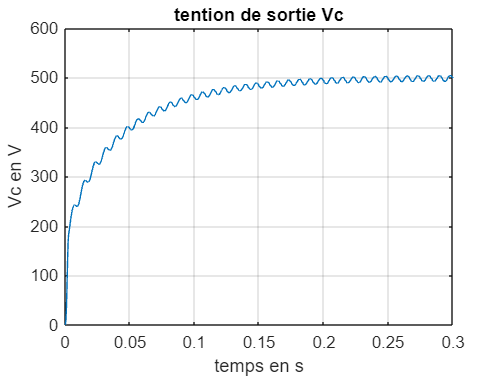

plot(ans.Vc.Time, ans.Vc.Data);
title("tention de sortie Vc");
ylabel("Vc en V");
xlabel("temps en s");
grid on;

fdec = 1/(0.12089-.120842)

fdec = 2.0833e+04

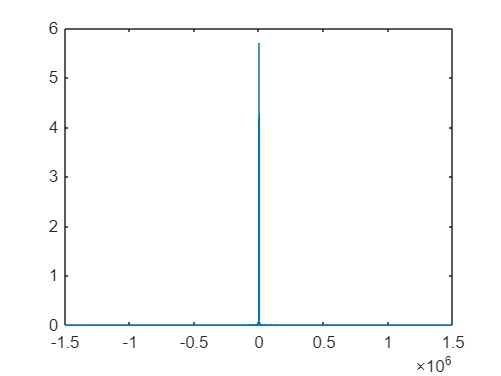

%TRACE DE LA FFT 

% % Calcul de la transformée de Fourier
% Y = fft(ans.Il.Data);
% 
% % Calcul des fréquences correspondantes
% fspec = Fs*(-len/2:len/2-1)/len;
% 
% % Shift du spectre pour le rendre bilatéral
% Y = fftshift(Y);
% P2 = abs(Y/len); % Divisez par la longueur du signal pour conserver l'amplitude

df = -len/2:1:len/2;%
X =fftshift(fft(ans.Il.Data)); % ramène les valeurs vers le zéro
X_mag = abs(X/len); % permet de conserver la valeur absolue des rais FFT
plot(df,X_mag,"lineWidth",1);


periodogram(ans.Il.Data)

Unexpected error during communication with services required to run MATLAB (error 5006).

Troubleshoot this issue by visiting: 
<a href="https://www.mathworks.com/support/lme/5006">https://www.mathworks.com/support/lme/5006</a>

% % Tracé du spectre bilatéral
% figure;
% P1 = P2(1:len);
% plot(fspec,P1); grid on;
% title('Spectre bilatéral du signal')
% xlabel('Fréquence (Hz)')
% ylabel('|P1(f)|')


% Tracée de l'hystérésis
Sr = 1;
dx = 0.01;
delta = 0;
x = -delta:dx:delta;
x0 = -(delta + H); x1 = -(delta - H); x2 = (delta - H); x3 = (delta + H);
x = (-25:dx:25);
yr = zeros(length(x),1);
yr1 = zeros(length(x),1);

IDx0 = x<=x0; yr(IDx0) = -Sr; 
IDx1 = (x>x0)&(x<=x2); yr(IDx1) = 0;
IDx2 = x>x2; yr(IDx2) = Sr;

IDx3 = x<=x1; yr1(IDx3) = -Sr;
IDx4 = (x>x1)&(x<=x3); yr1(IDx4) = 0;
IDx5 = x>x3; yr1(IDx5) = Sr;

plot(x, yr,"b", LineWidth=1)
hold on
plot(x, yr1,"b", LineWidth=1)


% xlabel("Epsilon")
% ylabel("U")
% title("SNL")
% axis([-1 1 -1.5 1.5])
% grid on
% hold off


fdec_initial= 1/(0.020844-0.0208215)
fdec_hysteresis= 1/(0.104136-0.104086)
fdec_hysteresis1= 1/(0.112424-0.112365)

fdec_hysteresis2= 1/(0.14587-0.145822)

